# **X-Ray Processing Steps**    

**By Banuka Liyanage, University of Moratuwa, Sri Lanka.                                        **

Import X-Ray dicom data and adjust the contrast to highlight the spine, later I will be finding a distance from a certain point on the image and find the pixel distnace , however the pixel distnace has no real use in real world applications thus this will be converted into a real world unit that has a real meaning in the medical domain. 

What is DICOM?

**Digital Imaging and Communications in Medicine (DICOM)** is the international standard for transmitting, storing, retrieving, printing, processing, and displaying medical imaging information.

DICOM image files are sourced from different modalities, either standalone or integrated. DICOM format files (or simply DICOM files) are stored with the file extension ".dcm." DICOM can accept other popular file formats such as JPEG, TIFF, GIF, and PNG.

## **Step one: Import DICOM**

Load the file and extract a single frame for processing.

backXray= medicalImage('back view01.dcm')

backXray =   medicalImage with properties:

          Pixels: [2971×1575 uint16]
        Colormap: []
    SpatialUnits: "mm"
       FrameTime: []
       NumFrames: 1
    PixelSpacing: [0.1390 0.1390]
        Modality: 'CR'
    WindowCenter: 2048
     WindowWidth: 4096


img=extractFrame(backXray,1);

Now Let's preview the raw data.

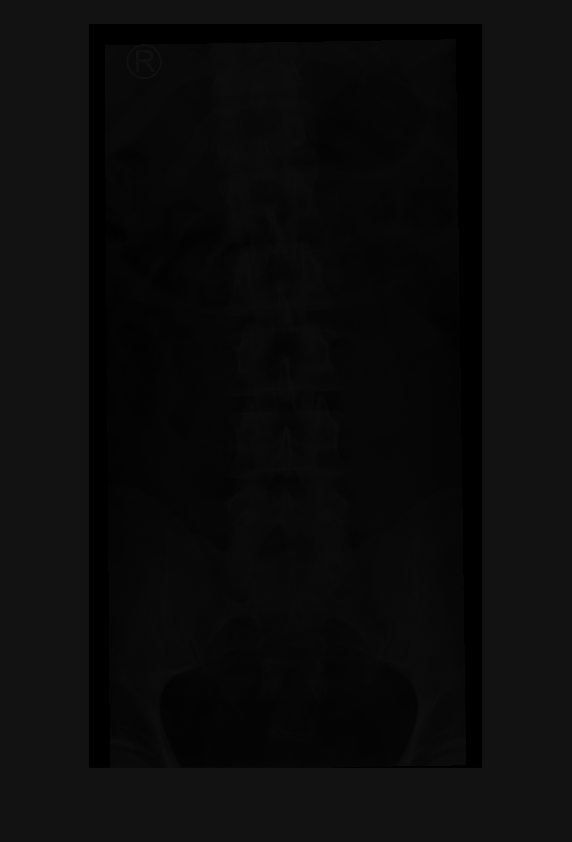

imshow(img)

Now as you can see the image of the X-Ray is not clearlt visible due to the lower contrast thus we need to adjust the contrast properly according to the data given by the DCIM properties in step one.

## **Step Two: Adjust the Contrast **

Display the image using the WindowCenter and WindowWidth values stored in the metadata.

Use these values to calculate the display range limits, which are passed into imshow. 

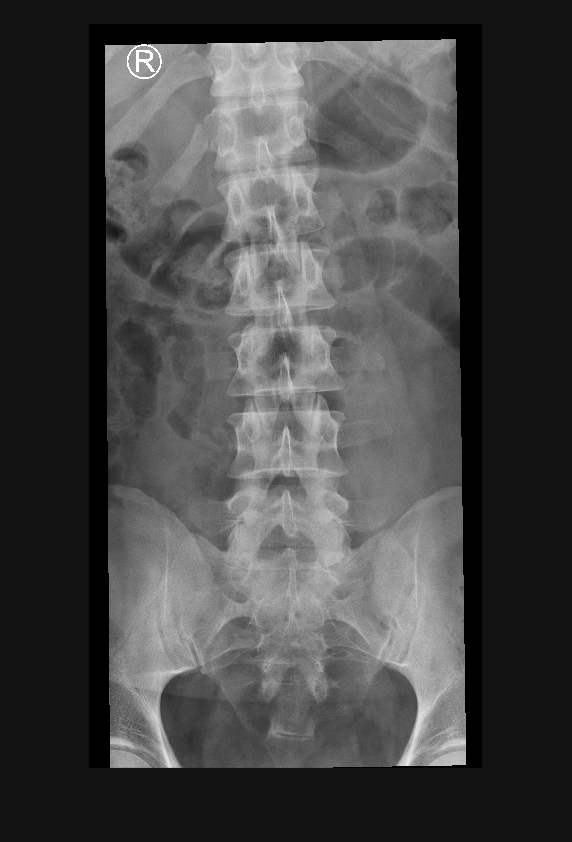

minVal = backXray.WindowCenter - backXray.WindowWidth/2;
maxVal = backXray.WindowCenter + backXray.WindowWidth/2;

imshow(img,[minVal,maxVal])

## **Step Three : Contrast Stretching**

Specifying a display range affects how the image is displayed, but does not modify the actual pixel values.

Use imadjust to modify the pixel intensity values , this will increase the contrast of the image by mapping the values between the specified display range to the full range of values supported by the data type of the image. 

This is a linear mapping with the following conditions :

- values <800 are assigned to a value of 0.

- values betwwen 800 and 3500 are linearly mapped to values between 0 and 1.

- values >3500 are assigned to a value of 1.

The display range of values are normalized by the maximum value supported by the data type (in this case this is uint_16 thus 2^16-1 ,  i.e 65535)

imgAdj= imadjust(img,[800 3500]/65535);

The adjusted pixel  intensity values now range from 0 to 65535, as shown in the following histogram. 

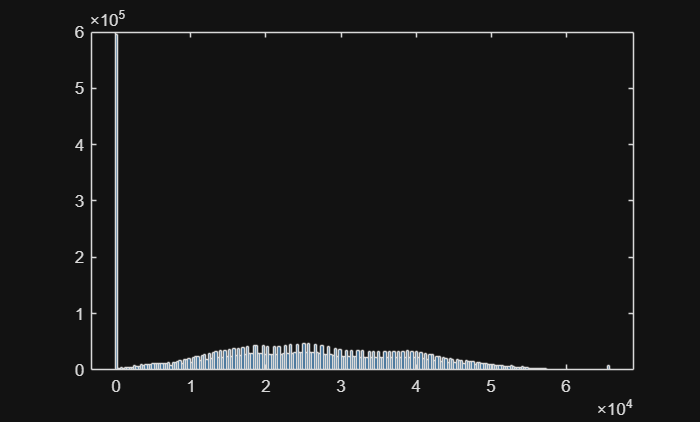

figure 
histogram(imgAdj)

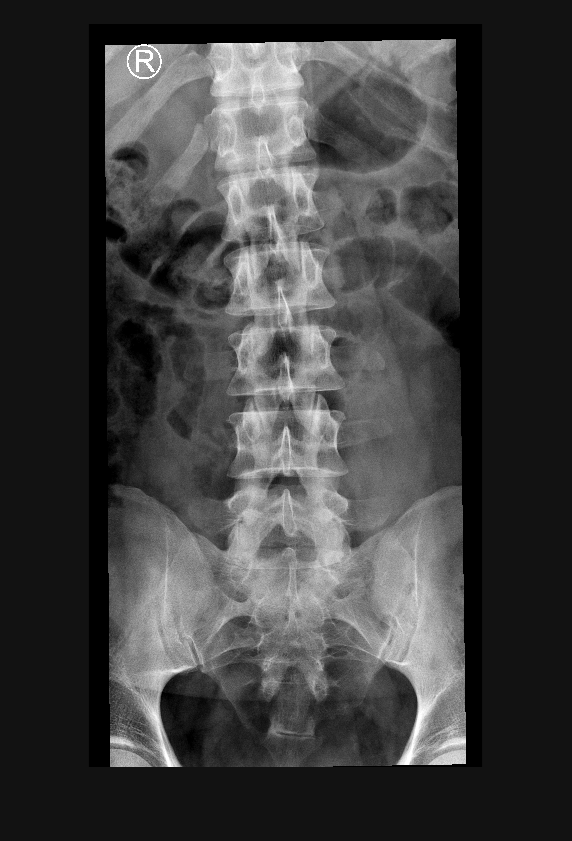

imshow(imgAdj)

The above image shows the spinal code clearly from the X-Ray after adjusting the pixels, using the image viewer app in Matlab we can manually adjust the contrast of the image and further measure certain distances too using the measure tool available in Image viewer.

## Measuring Distance

Using the Image viewer app in matlab we can measure the distance between two points on the image and export the values (distance in pixels and the starting and ending coordinates) to the workspace and use it for further analysis. 

img= extractFrame(backXray,1);

D1.Value_mm=D1.Value*backXray.PixelSpacing(1)

D1 = struct with fields:
    Position: [2×2 double]
       Value: 262.9069
    Value_mm: 36.5441


So the distanve between the selected two points in the image is 262.9069 in pixels , however this has no real use in real world thus I converted it to mm using the command "D1.Value_mm=D1.Value*backXray.PixelSpacing(1)" and this value is 36.5441 mm. 

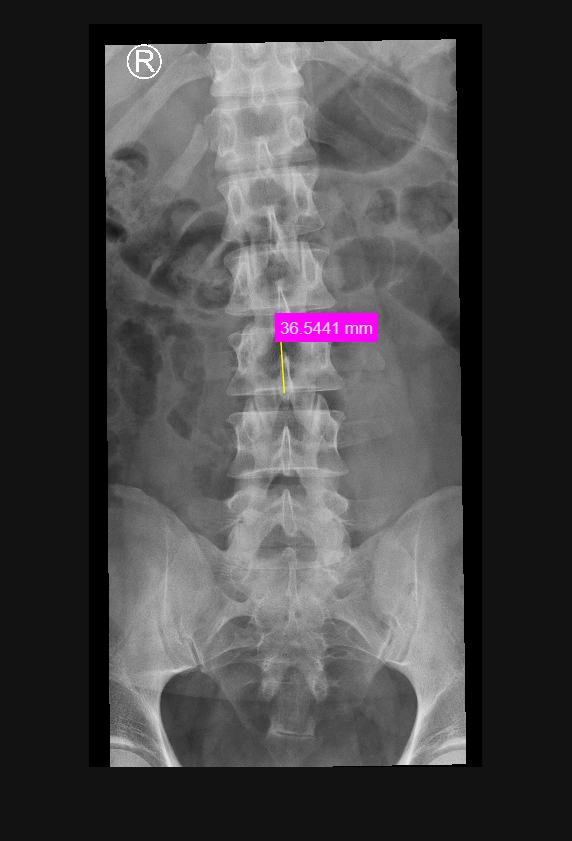

imshow(im)
line(D1.Position(:,1),D1.Position(:,2),'Color','y')
text(D1.Position(1,1), D1.Position(1,2), string(D1.Value_mm)+ " mm",'BackgroundColor','m')

This shows the distance I wanted to measure.

Save all the work and use for future processing, 

Thank you. 